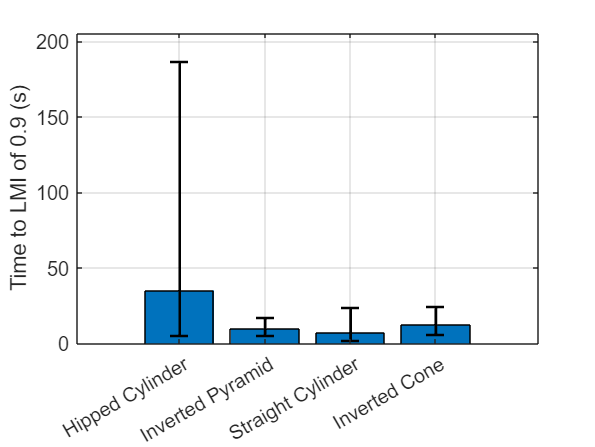

% Labels
labels = { ...
    'Hipped Cylinder', ...
    'Inverted Pyramid', ...
    'Straight Cylinder', ...
    'Inverted Cone'};

% Arithmetic means
meanVals = [ ...
    35.0844, ...
     9.6556, ...
     6.9506, ...
    12.2211];

% Log-space 95% CI bounds
CI_lower = [ ...
     4.90, ...
     5.14, ...
     1.68, ...
     5.82];

CI_upper = [ ...
    186.5, ...
     17.4, ...
     23.5, ...
     24.3];

% Convert to asymmetric error bars
errLower = meanVals - CI_lower;
errUpper = CI_upper - meanVals;

% Plot
figure;
b = bar(meanVals);
hold on;

x = 1:length(meanVals);

errorbar(x, meanVals, errLower, errUpper, ...
    'k', ...
    'LineStyle','none', ...
    'LineWidth',1.5, ...
    'CapSize',10);

% Formatting
set(gca,'XTick',x,'XTickLabel',labels);

ylabel('Time to LMI of 0.9 (s)');
grid on;
box on;
set(gca,'FontSize',11);

% Axis limits (important for large CI)
ylim([0 max(CI_upper)*1.1]);